# Matrix population model -  Wandering albatross

#### By Joanie Van de Walle - 28/04/2022

### Life cycle

#### The first stage is PB1 which corresponds to chicks, age 0, at fledging). Pre-breeder stages are PB1 through PB16, with corresponding ages 0 through 15. Individuals may start transiting to the breeding stages upon PB6 (age 5) and become either SB or FB at the age of 6. Then, breeding transitions are SB, FB, PSB, PFB and NB 6 through 31, which correspond to ages 6 to 31+. However, transitions from PSB and PFB can only start from age 7 onward and transitions from NB can only start from age 8 onward.

### 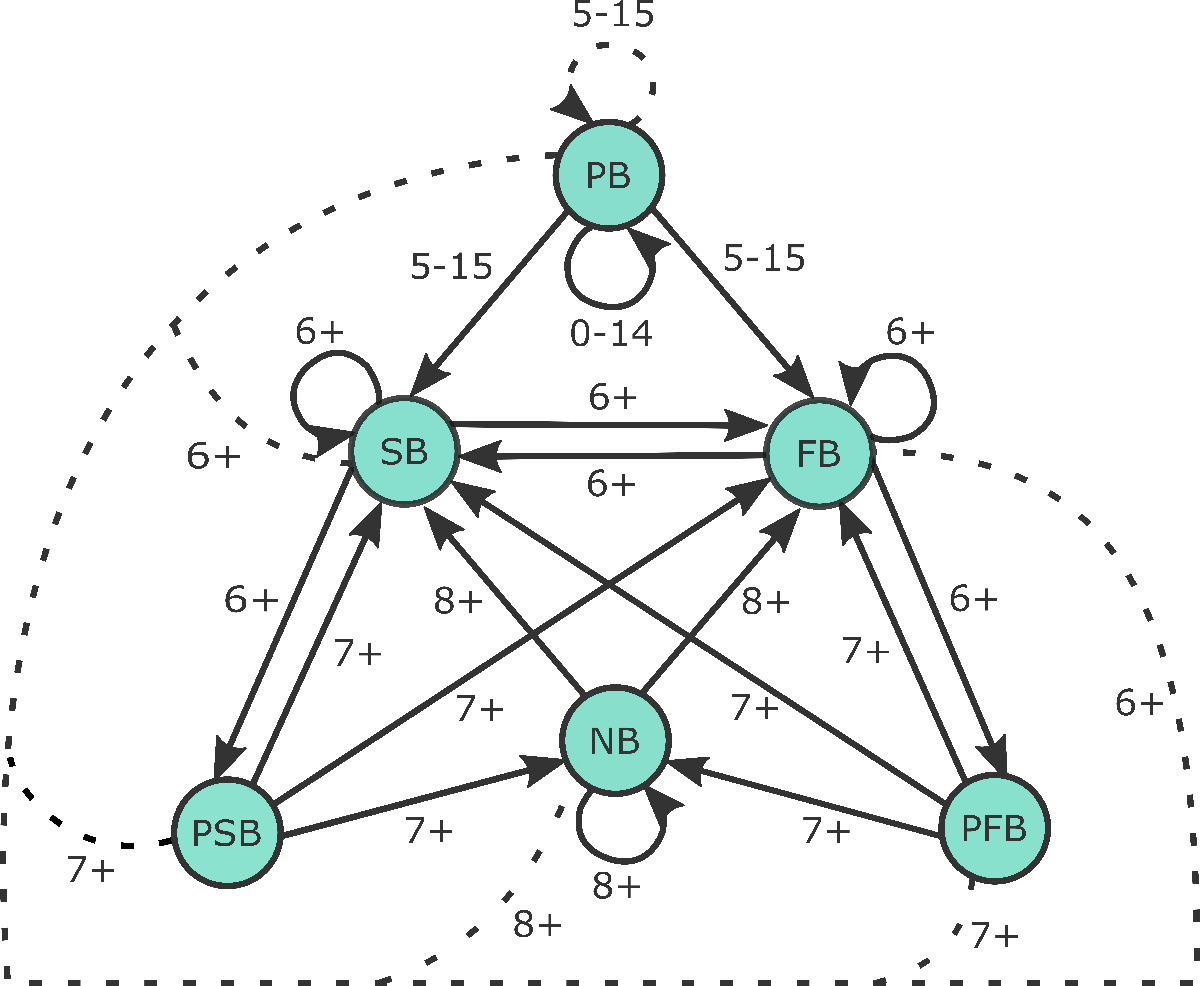

### Parameters and initial information

clc;clear;

% Load parameters
parameters

% Load important initial informations
Info_init

### Population analysis with personality

#### Females and Males 

#### Without uncertainties

% Matrix of personality effects. 
alpha_matrix % This gives the ALPHA matrix

% Perform population analysis. 
pop_analysis_perso % this gives the theta and lambda vectors as well as the u and f matrices for each personality score

% Figure of the impact of personality on lambda
figure_lambda_perso

### Population analysis with personality

#### Females and Males 

#### With uncertainties on the effect of personality

% Run the simulation to obtain life history outcomes (Life expectancy, lifetime reproductive success and lambda)
LHO % takes a long time to run

% Export the output to produce graphs in R
save("Lambda_pers_uncertaintiesF_2008_SCALE.mat", "lambdas_f");
writematrix(lambdas_f, "Lambda_pers_uncertaintiesF_2008_SCALE.txt",'Delimiter','tab');
writematrix(LEX_f, "Expectancy_pers_uncertaintiesF_2008_SCALE.txt",'Delimiter','tab');
writematrix(Occup_sb_f, "OccupancySB_pers_uncertaintiesF_2008_SCALE.txt",'Delimiter','tab');

save("Lambda_pers_uncertaintiesM_2008_SCALE.mat", "lambdas_m");
writematrix(lambdas_m, "Lambda_pers_uncertaintiesM_2008_SCALE.txt",'Delimiter','tab');
writematrix(LEX_m, "Expectancy_pers_uncertaintiesM_2008_SCALE.txt",'Delimiter','tab');
writematrix(Occup_sb_m, "OccupancySB_pers_uncertaintiesM_2008_SCALE.txt",'Delimiter','tab');

% Figures are produced in R LHO_Figures.R

### Occupancy times

% Run the script
OccupancyTimes % requires running alpha_matrix first

% Save
writematrix(occ_males, "OccupancyM.txt",'Delimiter','tab');
writematrix(occ_females, "OccupancyF.txt",'Delimiter','tab');

% Figures are produced in R OccupancyTimes.R

### Return times

% Run the script
ReturnTimes % requires running alpha_matrix first

% Save
save("returntimesSBB.mat", "returntimesSBB");
save("returntimesFBB.mat", "returntimesFBB");
save("returntimesSBB_f.mat", "returntimesSBB_f");
save("returntimesFBB_f.mat", "returntimesFBB_f");

% Figures are produced in R script ReturnTimes.R